# Atividade 05_01

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Filtro da média

Obtenha: (i) uma máscara de convolução do filtro da média 3x3 (box filter) sem usar a função fspecial e mostre-a em um gráfico 3D utilizando a função bar3; (ii) uma máscara de convolução do filtro Gaussiano de sigma=1 e janela 5x5 sem usar a função fspecial e mostre-a em um gráfico 3D utilizando a função bar3.

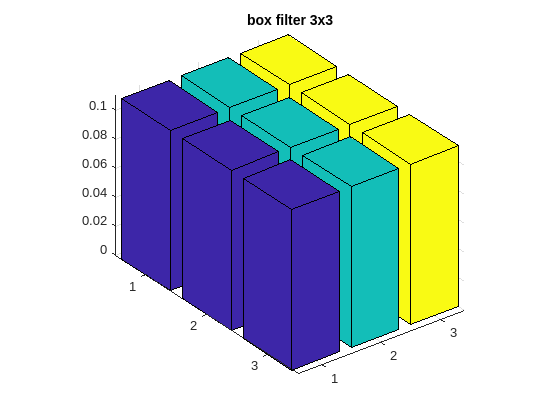

boxFilterSize = 3;
boxFilterMask = zeros(boxFilterSize, boxFilterSize) + 1 / (boxFilterSize * boxFilterSize);
figure, bar3(boxFilterMask)
title("box filter " + boxFilterSize + "x" + boxFilterSize)

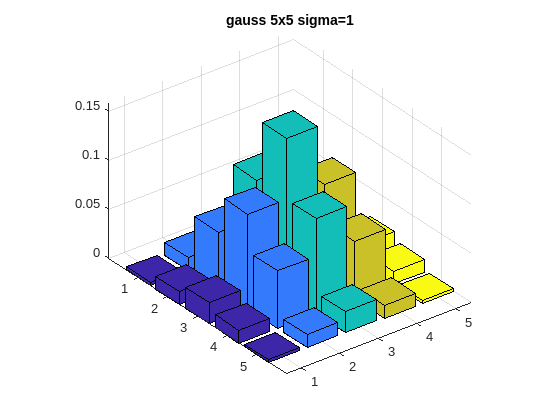



gaussKernelSize = 5;
gaussGridSize = floor(gaussKernelSize/2);
gaussSigma = 1;
[X,Y] = meshgrid(-gaussGridSize:gaussGridSize, -gaussGridSize:gaussGridSize);
v = gaussSigma^2;
gauss1 = (1/(2*pi*v))*exp(-(X.^2+Y.^2)/(2*v));
figure, bar3(gauss1)
title("gauss " + gaussKernelSize + "x" + gaussKernelSize +  " sigma=" + gaussSigma)